## Pendulum Minimum Time

tau_max = 200;
m = 10;
l = 2;
L = pi*l;
g0 = 9.81;
Ic = (1/12)*10*4;
d = l/2

d = 1

I = Ic+m*(d^2)

I = 13.3333


theta_dot_dot_max = (tau_max-(m*g0*d*sin(pi/6)))/(I) 

theta_dot_dot_max = 11.3213

T = sqrt((16*pi)/(3*theta_dot_dot_max))

T = 1.2165

### Plot

%  BANG-COAST-BANG SWING-UP 
clear; clc;

% Given/problem data
tau_max = 200;         % [Nm] motor max torque
m       = 10;          % [kg] rod mass
l       = 2;           % [m]  rod length
g0      = 9.81;        % [m/s^2] gravity
Ic      = (1/12)*m*l^2;    % centroidal inertia of uniform rod
d       = l/2;         % distance from pivot to CoM
I       = Ic + m*(0)^2; 
% ^ If your pivot is exactly at the rod end, you might not need + m*(0)^2.

% For a chosen "bang-coast-bang" approach, you might first guess or solve
% for T and the needed acceleration. Below is a simple approach using
% the formula you gave:
theta_dot_dot_max = (tau_max - m*g0*d*sin(pi/6)) / I;
% Or a simpler estimate ignoring gravity:
% theta_dot_dot_max = tau_max / I;

% Then from your formula:
T = sqrt((16*pi)/(3*theta_dot_dot_max));

fprintf('Using T = %.3f s\n', T);

Using T = 0.608 s


fprintf('Using ddot_theta_max = %.3f rad/s^2\n', theta_dot_dot_max);

Using ddot_theta_max = 45.285 rad/s^2


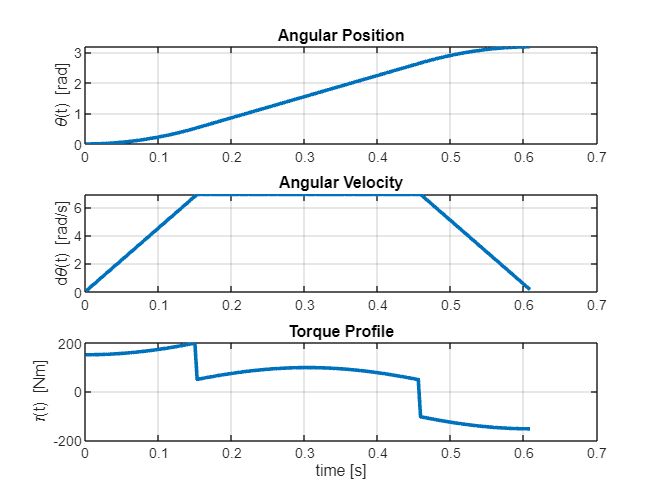


% --- Time partition ---
T_s = T/4;           % acceleration phase
T_c = T/2;           % coasting phase
N   = 200;           % number of points for plotting
t   = linspace(0, T, N);
dt  = t(2)-t(1);

% --- Allocate arrays ---
theta   = zeros(size(t));  % angular position
dtheta  = zeros(size(t));  % angular velocity
ddtheta = zeros(size(t));  % angular acceleration
tau     = zeros(size(t));  % motor torque

% --- 1) Define piecewise acceleration ddtheta(t) ---
for i = 1:N
    if t(i) <= T_s
        % first bang (accel)
        ddtheta(i) = +theta_dot_dot_max;
    elseif t(i) <= (T_s + T_c)
        % coast
        ddtheta(i) = 0;
    else
        % final bang (decel)
        ddtheta(i) = -theta_dot_dot_max;
    end
end

% --- 2) Numerically integrate to get theta, dtheta ---
for i = 2:N
    dtheta(i) = dtheta(i-1) + ddtheta(i-1)*dt;
    theta(i)  = theta(i-1)  + dtheta(i-1)*dt + 0.5*ddtheta(i-1)*dt^2;
end

% If your problem wants 0 -> pi swing, you may rescale or adjust T, etc.
% This basic code shows the shape of the bang-coast-bang.  

% --- 3) Compute torque(t) including gravity ---
for i = 1:N
    tau(i) = I*ddtheta(i) + m*g0*d*sin(theta(i));
    % If your pivot is at top, check sign convention. 
    % If your formula has a minus sign, adjust accordingly.
end

% --- 4) Plots ---
figure;
subplot(3,1,1);
plot(t, theta, 'LineWidth',2);
ylabel('\theta(t) [rad]');
title('Angular Position'); grid on;

subplot(3,1,2);
plot(t, dtheta, 'LineWidth',2);
ylabel('d\theta(t) [rad/s]');
title('Angular Velocity'); grid on;

subplot(3,1,3);
plot(t, tau, 'LineWidth',2);
xlabel('time [s]');
ylabel('\tau(t) [Nm]');
title('Torque Profile'); grid on;